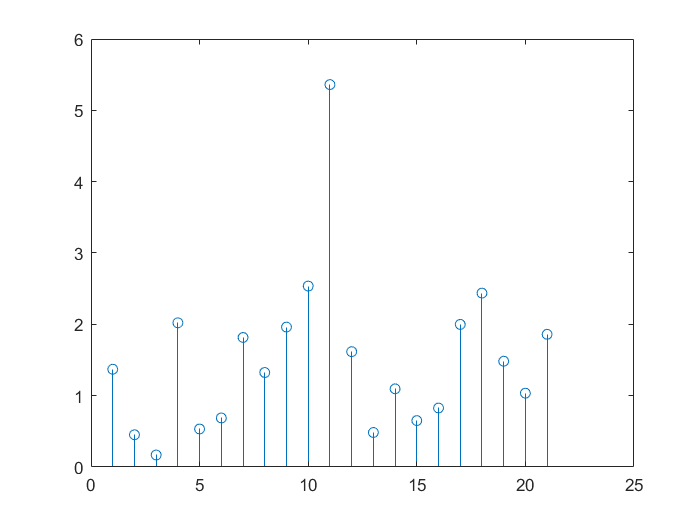

% 设置随机数生成器种子
rng(123);

% 生成复高斯白噪声
noise = randn(1000000, 1) + 1i * randn(1000000, 1);

% 求噪声的模
modulus = abs(noise);

% 找到最大值及其位置
[max_value, max_index] = max(modulus);

stem(modulus(max_index - 10:max_index + 10));


% 对模值进行排序
sorted_modulus = sort(modulus);

% 确定倍数门限
multiplier = 0.2;

disp(['最终门限倍数: ', num2str(multiplier)]);

最终门限倍数: 0.2



% 检测10组数据以验证门限
threshold = multiplier;
num_detected_list = zeros(10, 1);

for group = 1:10
    % 设置随机数生成器种子
%     rng(group);
    
    % 生成复高斯白噪声
    noise = rand(1000000, 1) + 1i * rand(1000000, 1);
    
    % 求噪声的模
    modulus = abs(noise);
    modulus2 = zeros(1e6,1);
    for i = 11 : 1e6 - 10
        modulus2(i-10) = mean(modulus(i-10:i+10));
    end
    
    % 统计超过门限的数据点个数
    num_detected = sum(modulus2 > threshold * max_value);
    num_detected_list(group) = num_detected;
    
    disp(['第', num2str(group), '组超过门限的数据点个数为: ', num2str(num_detected)]);
end

第1组超过门限的数据点个数为: 0
第2组超过门限的数据点个数为: 0
第3组超过门限的数据点个数为: 0
第4组超过门限的数据点个数为: 0
第5组超过门限的数据点个数为: 0
第6组超过门限的数据点个数为: 0
第7组超过门限的数据点个数为: 0
第8组超过门限的数据点个数为: 0
第9组超过门限的数据点个数为: 0
第10组超过门限的数据点个数为: 0



disp(['最大值为: ', num2str(max_value)]);

最大值为: 5.3609


disp(['最大值的位置为: ', num2str(max_index)]);

最大值的位置为: 450931


disp(['10组数据超过门限的统计: ', num2str(num_detected_list')]);

10组数据超过门限的统计: 0  0  0  0  0  0  0  0  0  0
